## Example 1.1

Plot $f(x) = (x-1)^2$ over the domain $x \in [0, 2]$ 

f = @(x) (x-1).^2   % anonymous function

f = function_handle with value:
    @(x)(x-1).^2


x = 0:0.01:2        

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


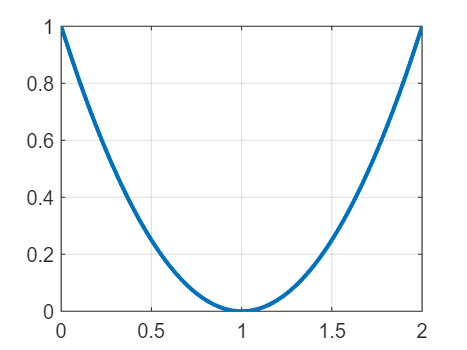


plot(x,f(x), 'linewidth', 2); grid;

## Example 1.2

Consider the ``corrugated spring'' function $f(R) = -\cos(kR) + 0.1R^2$ where $R$ is the radius $R = sqrt{(x_1-c_1)^2 + (x_2-c_2)^2}$, $c_1 = 5$, $c_2=5$, $k=5$. Draw

- a 3D plot of this function

- a contour plot of the function in variable space or $x_1-x_2$ space

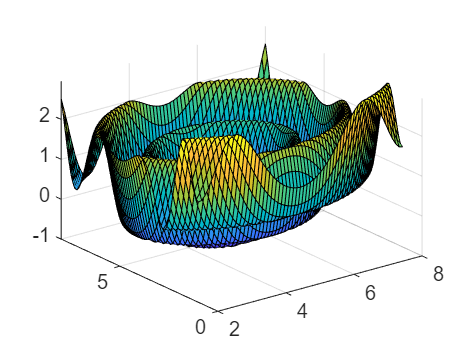

[x1, x2] = meshgrid(2:0.1:8, 1:0.1:8);
c1 = 5; c2 = 5; k = 5;
R = sqrt((x1-c1).^2 + (x2-c2).^2);
f = -cos(k*R) + 0.1*R.^2;

surf(x1, x2, f )

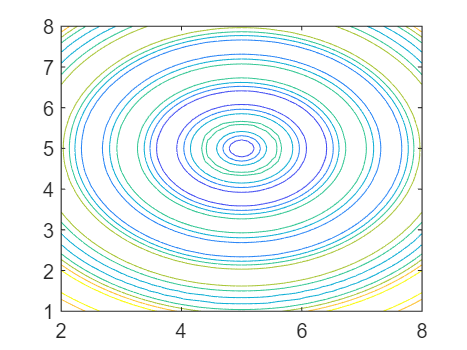

figure(2)
contour(x1, x2, f)

## Example 1.12

The plotting of feasible region $\Omega$ and objective function contours for the NLP problem


$$\begin{array}{l}
\underset{x_1 ,x_2 }{\textrm{minimize}} \;\;\;{\left(x_1 +2\right)}^2 -x_2 \\
\textrm{subject}\;\textrm{to}\;\;\;\frac{x_1^2 }{4}+x_2 -1\le 0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;2+x_{1\;} -2x_2 \le \;0
\end{array}$$


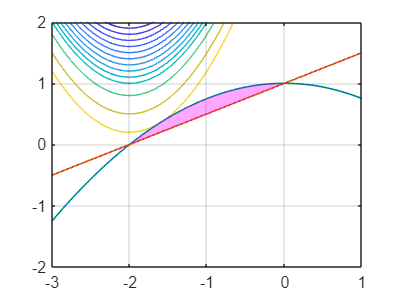

[x1, x2] = meshgrid(-3:0.01:1, -3:0.01:3);
g1 = x1.^2/4 + x2 -1;
g2 = 2 + x1 - 2*x2;
f = (x1+2).^2 -x2;


la = -1:-0.1:-2.0;
lb = [-0.2005, -0.5, -0.8];
contour(x1, x2, f, [la, lb])
hold on

contour(x1, x2, g2, [0 0], 'LineWidth',1, 'lineColor','red');
contour(x1, x2, g1, [0 0], 'LineWidth',1, 'LineColor','green') % level of g1 = 0


y1 = @(x) -x.^2/4 + 1;
y2 = @(x) 1 + x./2;
x = -3:0.1:1;

pgon1 = polyshape([ x(1) x x(end) ],[ y1(x(1)) y1(x) y1(x(end)) ], 'Simplify',false);
pgon2 = polyshape([x(1) x(1) x x(end) x(end)],[1.5 y2(x(1)) y2(x) y2(x(end)) 1.5], 'Simplify',false);

plot(x,y1(x),x,y2(x))
plot(intersect(pgon1,pgon2),'EdgeColor','none','FaceColor','m')
axis([-3 1 -2 2]); grid

hold off

f = @(x1,x2) (x1+2).^2 - x2

f = function_handle with value:
    @(x1,x2)(x1+2).^2-x2


g1 = @(x1,x2) x1^2/4 + x2 -1; 
g2 = @(x1, x2) 2 + x1 - 2*x2;

% plot constraints line
fimplicit(g1)

hold on
fimplicit(g2)
axis([-3 1 -2 2]); grid

% plot contour of f
la = -1:-0.1:-2.0;
lb = [-0.2005, -0.5, -0.8];
fcontour(f, 'LevelList', [la, lb], 'LineColor','blue')
legend('g1 constraint', 'g2 constrain', 'f contour', 'Location','southeast');

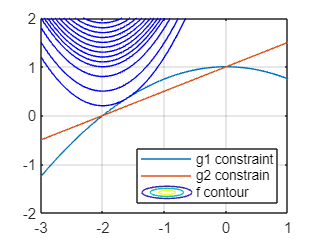

hold off